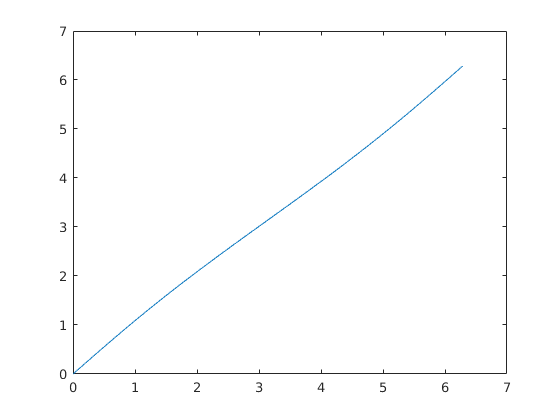

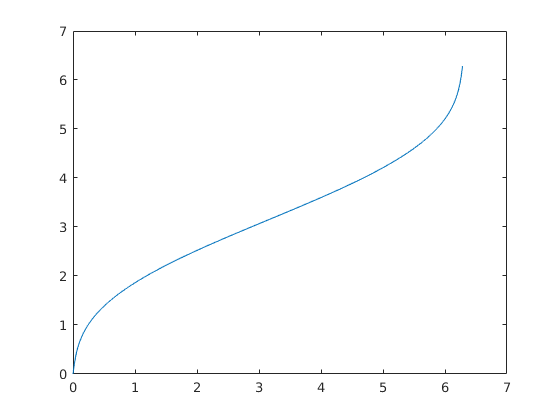

% problem 17: solve the kepler equation

% constants
n = 300; % steps to be taken
ecc = [0.1, 0.9]; % eccentricity
M = linspace(0, 2*pi, n); % mean anomoly

% calculate numerical and theoretical solutions
for i = 1:length(ecc) % for each value of eccentricity
    e = ecc(i);
    for k = 1:n % for each point in M
        % calculate numerical solution by newton's method
        % initial guess
        if k == 1
            E = 0.1;
        else
            E = E_num(k - 1);
        end
        % run 50 iterations newton's method
        for ii = 1:50
            f = E - e*sin(E) - M(k); % value of function
            df = 1 - e*cos(E); % derivative value
            E = E - (f / df); % compute next guess
        end
        E_num(k) = E; % put numerical value in accumulator
        
        % find theoretical solution
        sigma = 0; % store result of sum
        for jj = 1:400
            sigma = sigma + (1/jj) * besselj(jj, e*jj) * sin(jj*M(k));
        end
        E_theo(k) = M(k) + 2*sigma;
    end
    % plot results
    figure(i)
    plot(M, E_num)
    plot(M, E_theo)
end